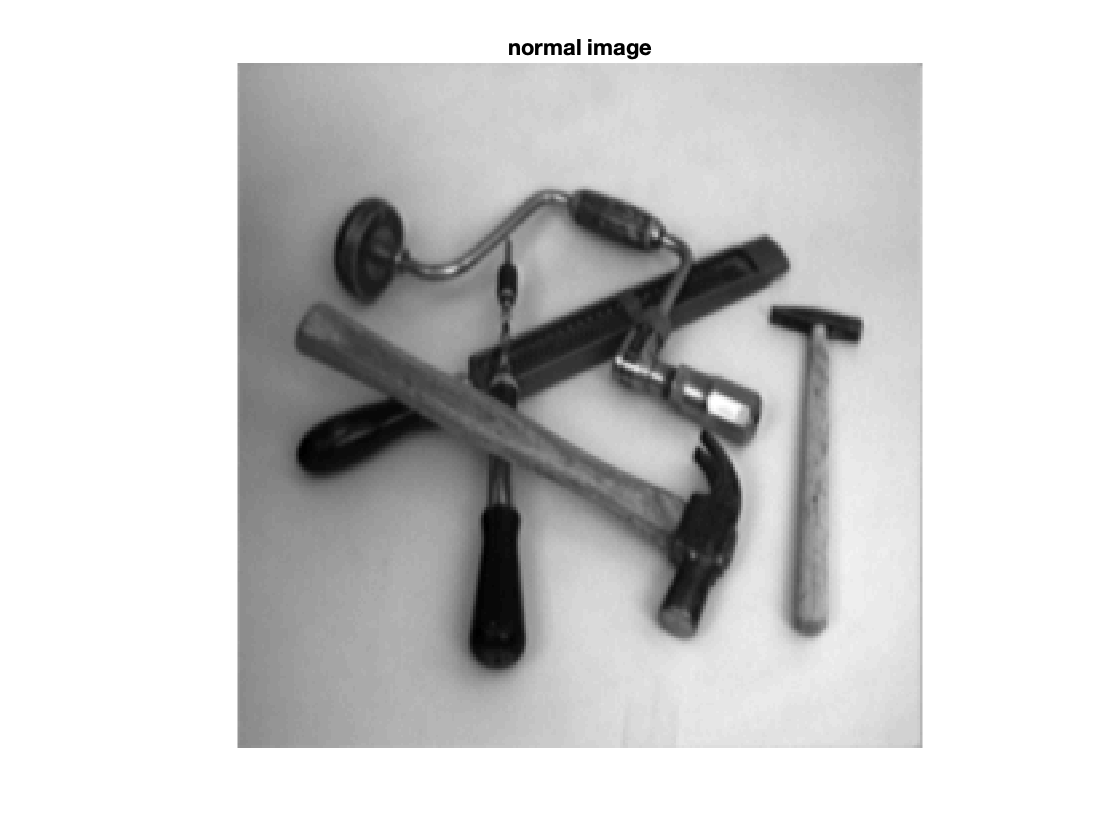


%tools = gaussfft(few256, 0.8); % blurring image makes it harder to detect edges.
tools =  discgaussfft(few256,0.5);
dx = zeros(256, 256);
dy = zeros(256, 256);
showgrey(tools)
title("normal image")

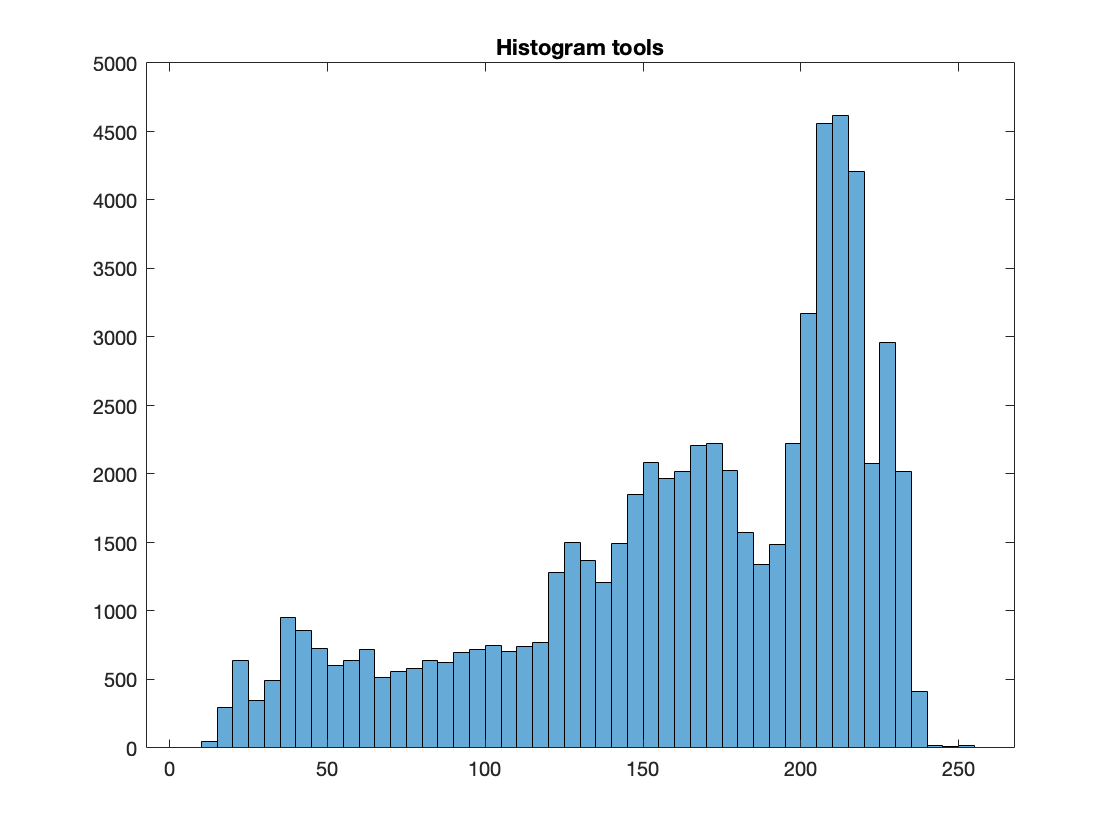

histogram(tools)
title("Histogram tools")

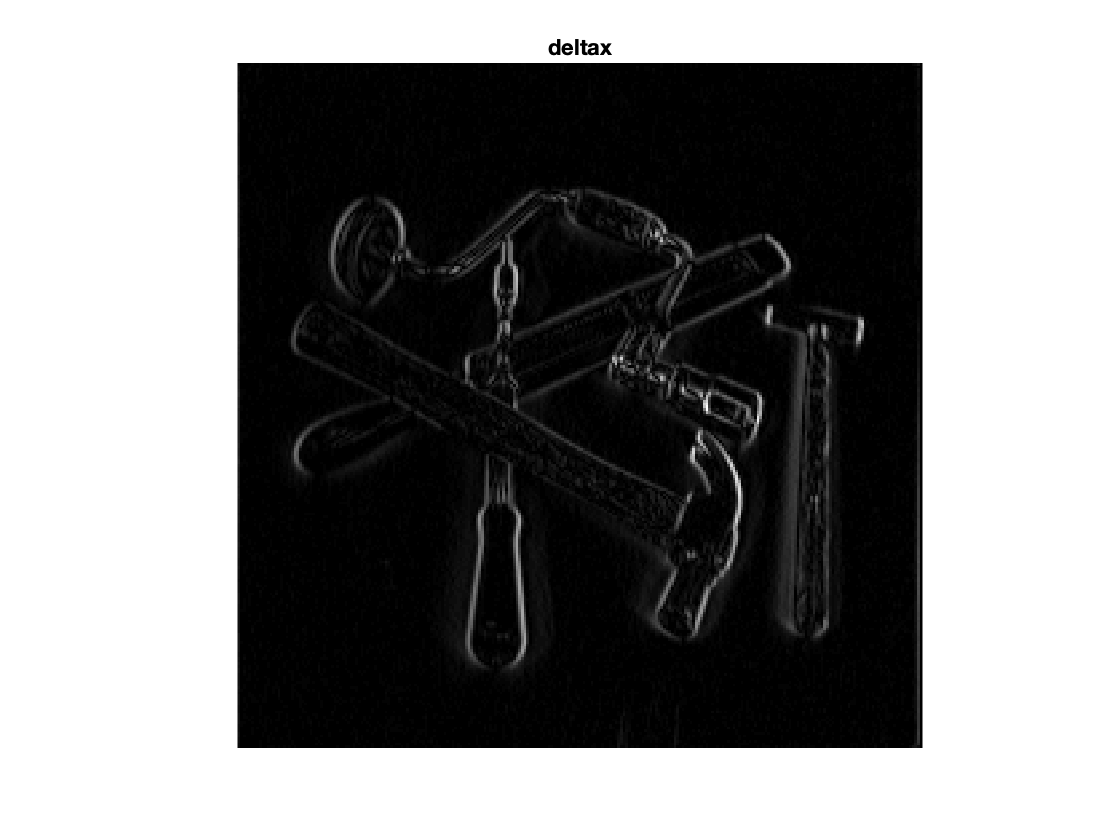


%for x derivative
dx = deltax(tools, 256, 255);
%for row = 1:256
%    for column = 1:255
%        dx(row,column) = deltax(tools,row,column);
%    end
%end
%dxtools = conv2(tools, dx, "same");
%showgrey(dxtools)
showgrey(sqrt(dx.^2))
title("deltax")

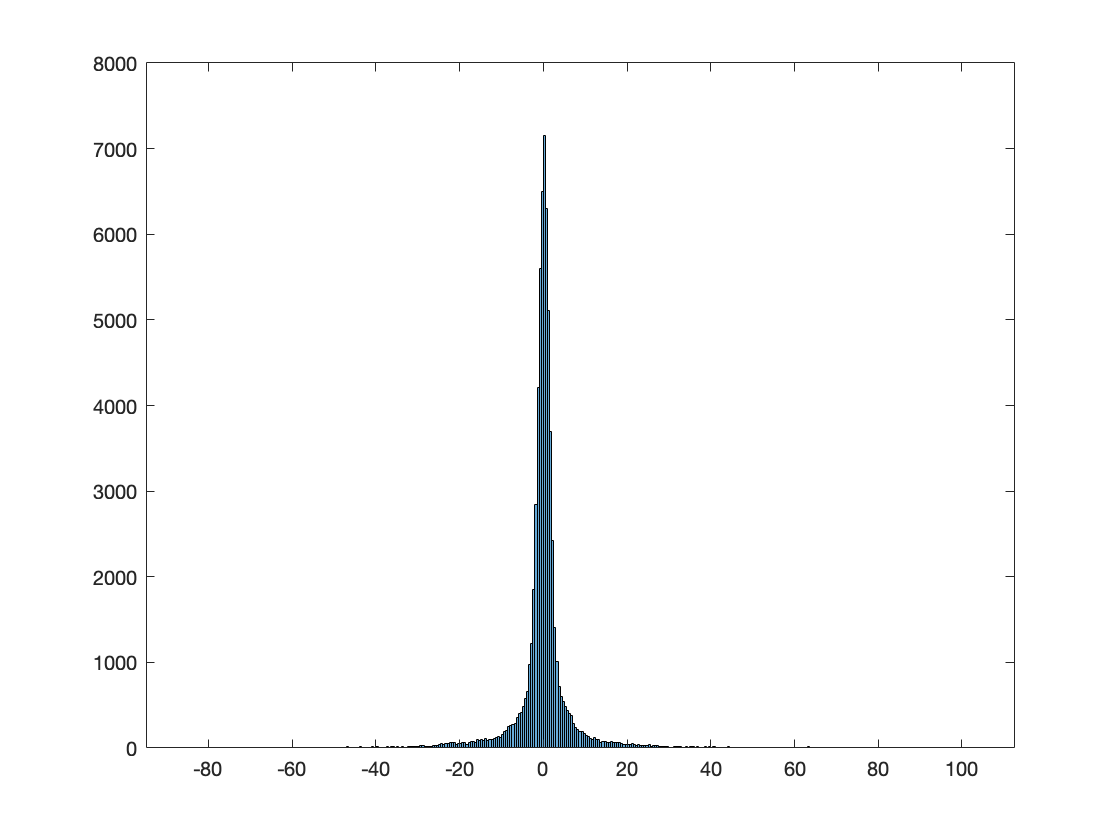

histogram(dx)

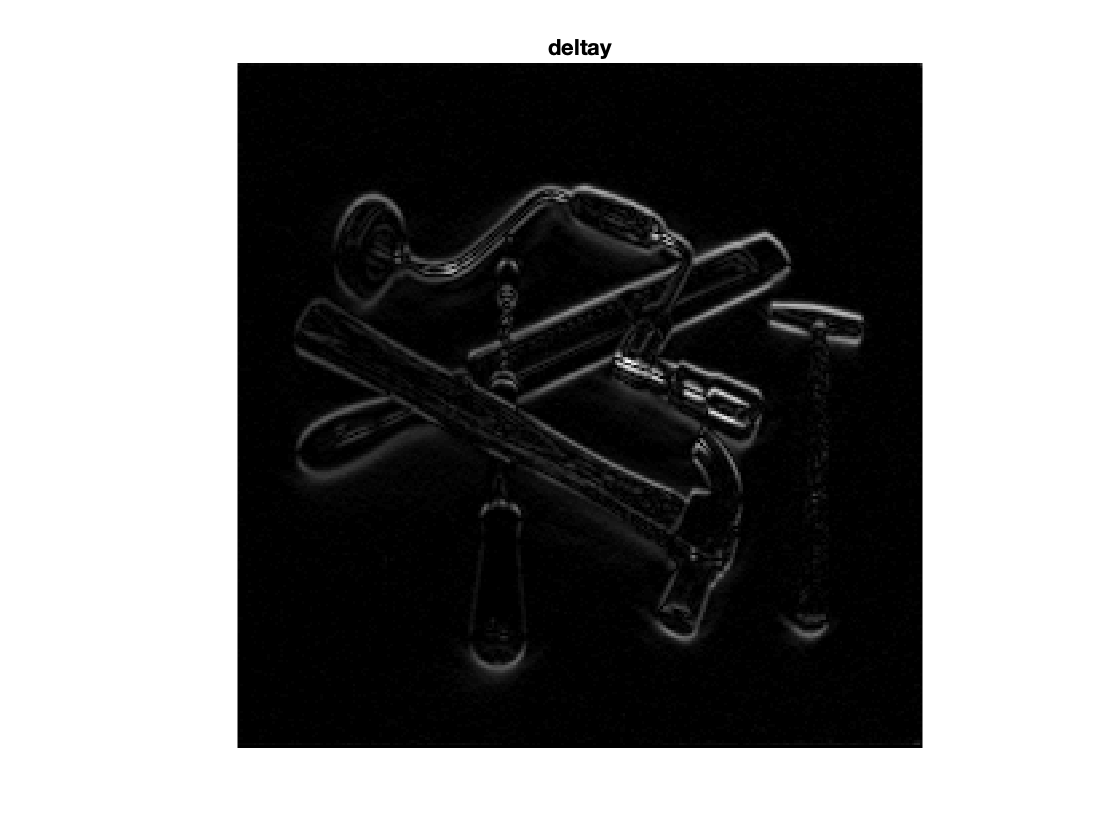



% for y derivative
%for column = 1:256
%    for row = 1:255
dy = deltay(tools, 255, 256);
%    end
%end
showgrey(sqrt(dy.^2))
title("deltay")

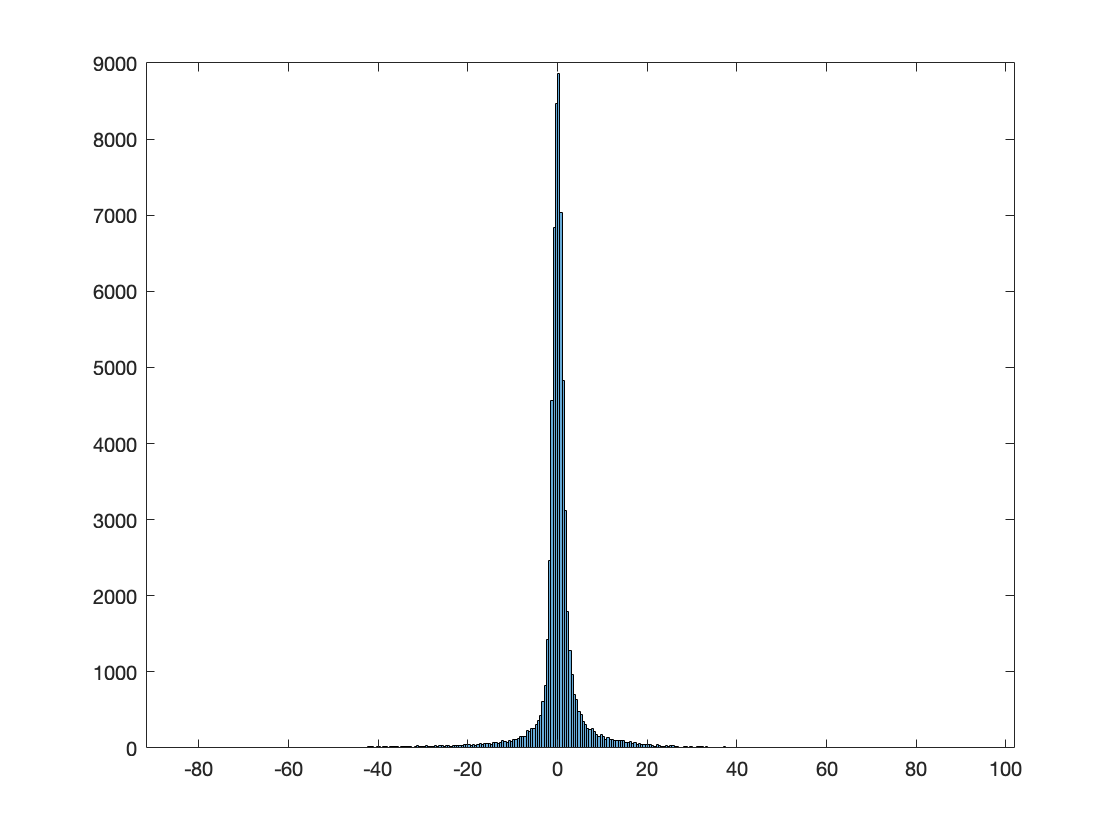

histogram(dy)

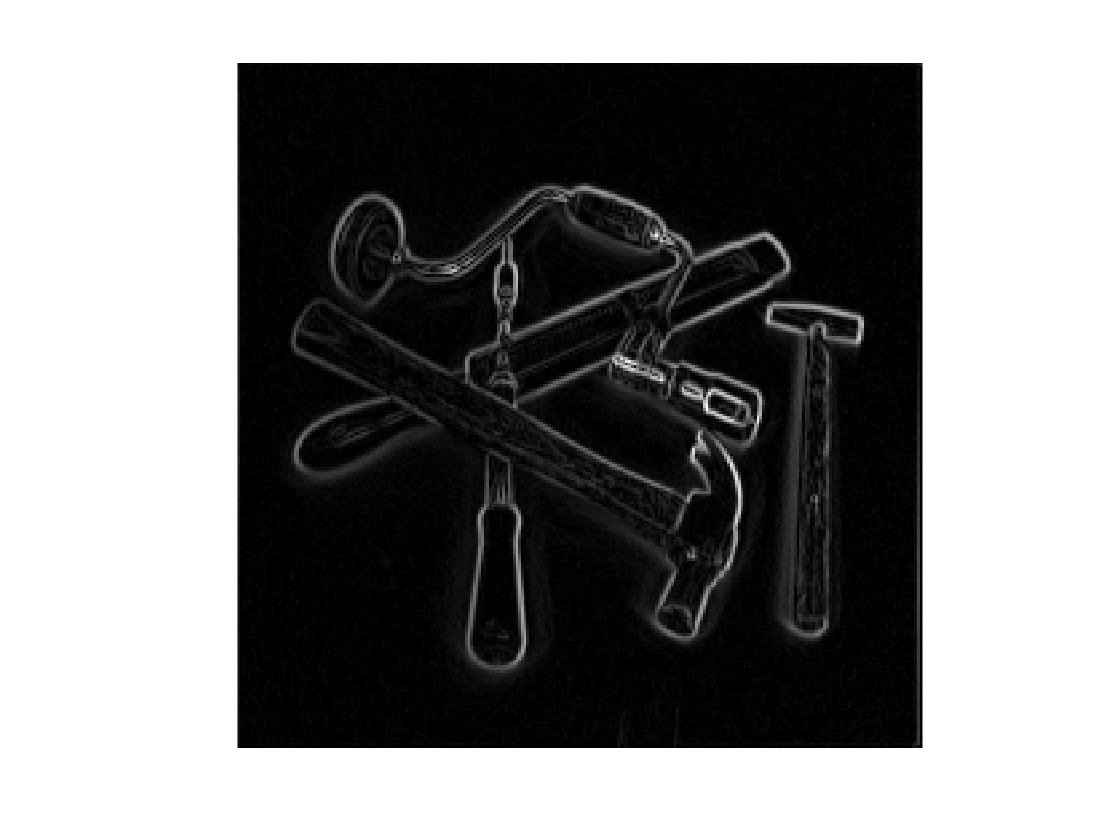


%dxdy = conv2(tools,dx,"full");
%sshowgrey(dxdy) % shows edges on image, but not clear. ??

gradmagntools = sqrt(dx .^2 + dy.^2);

showgrey(gradmagntools)

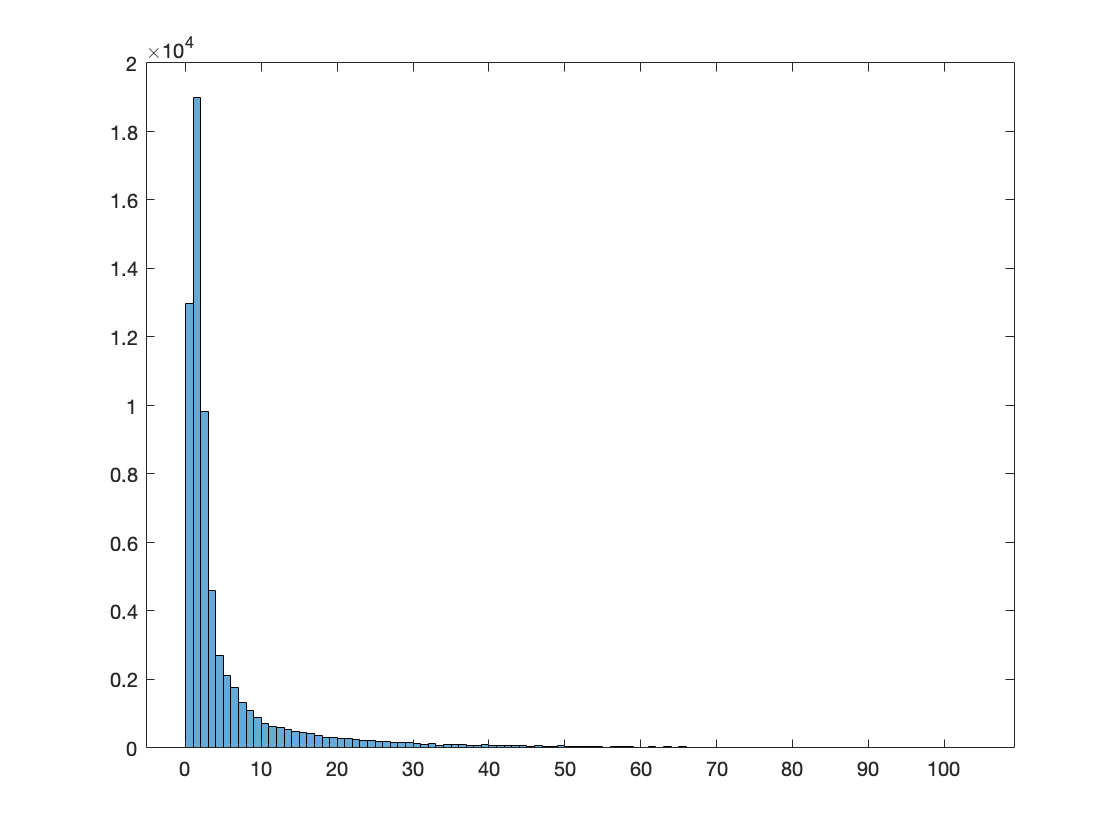

histogram(gradmagntools)

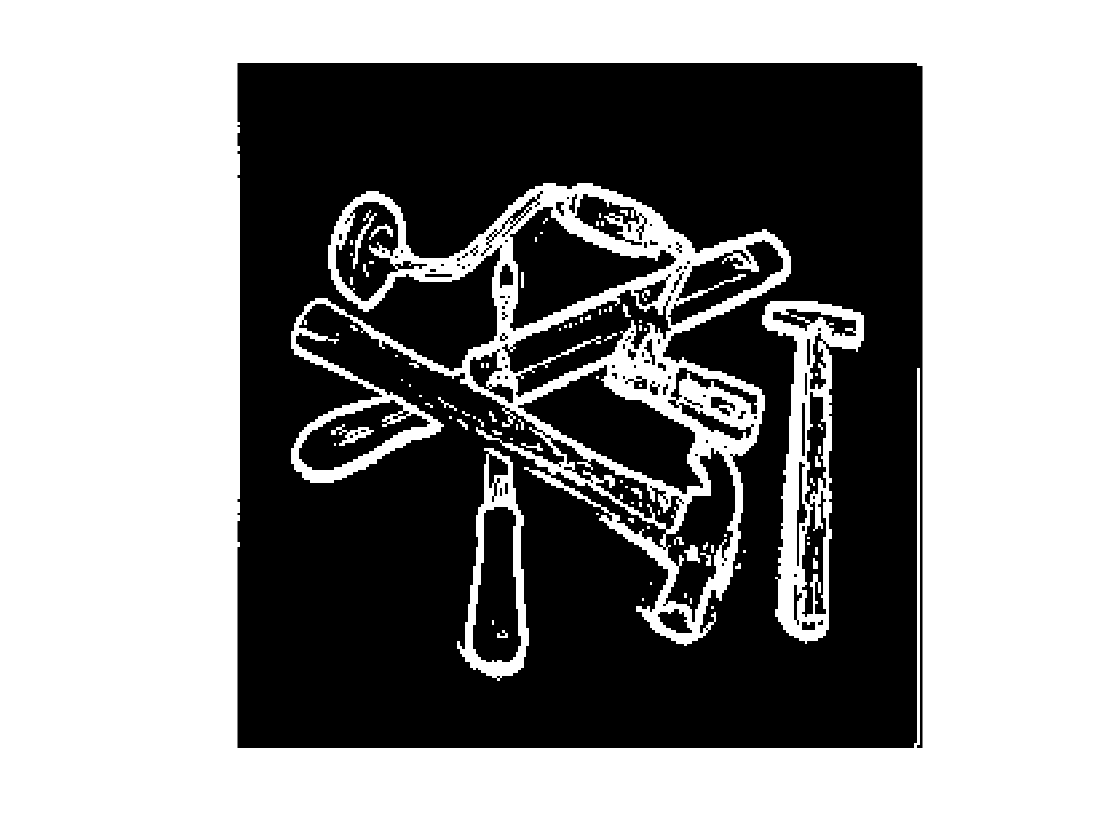

showgrey((gradmagntools-10)>0)



test = Lv(tools, 'same');

ans =    256   256


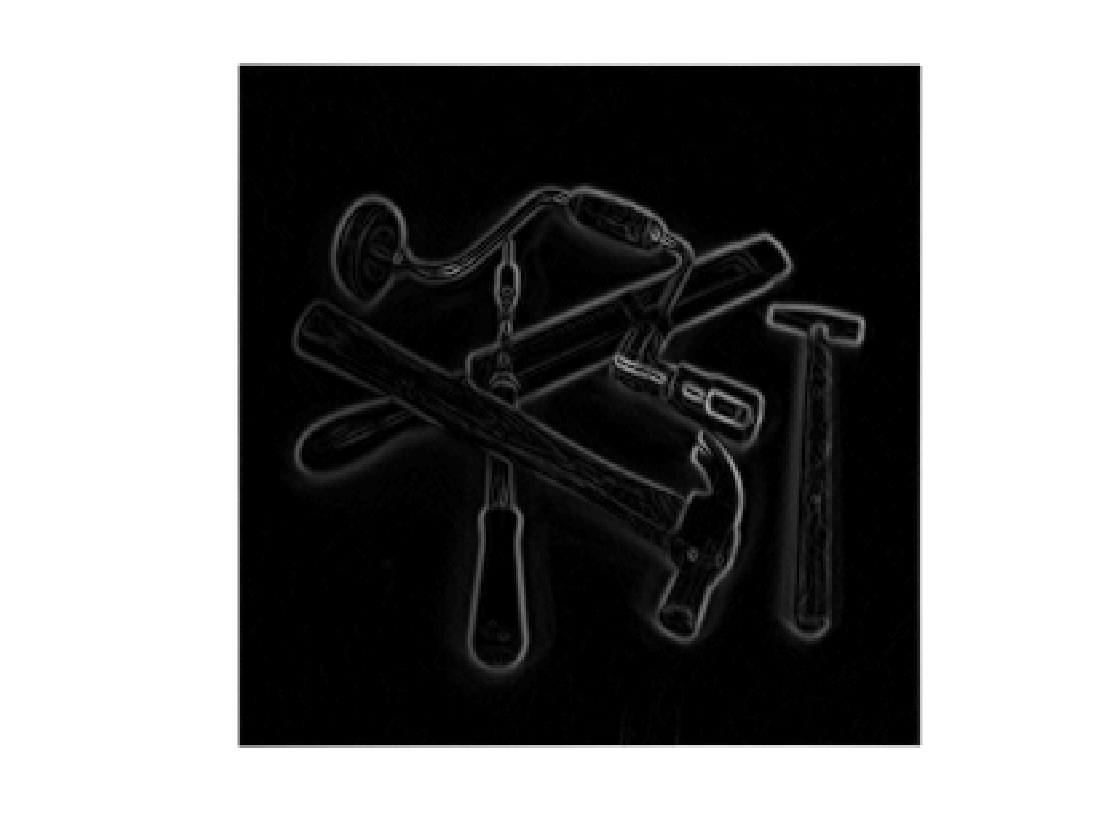

showgrey(test)